%This script reads pesticides data from the Faculta lab, having x samples.
%The pesticides appear in the list attached with the names.
close all
clear all
load pest_irr.txt;
load irr_dates.txt;date1=x2mdate(irr_dates);
lines = readlines("names_irr.txt");
load Irr_EC_Apr.txt;EC=Irr_EC_Apr(:,2);EC_date=Irr_EC_Apr(:,1);
x=5;%num of samples
% Plot time series of 4 days for each pesticides add title with the pestiide
% name
j=1

j = 1

ft=fittype('poly1')

ft =      Linear model Poly1:
     ft(p1,p2,x) = p1*x + p2

pestitle = 'Ametryn'

pestitle = 'Atrazine'

pestitle = 'Atrazine-Desethyl'

pestitle = 'Atrazine-Desisopropyl'

pestitle = 'Azoxystrobin'

pestitle = 'Boscalid'

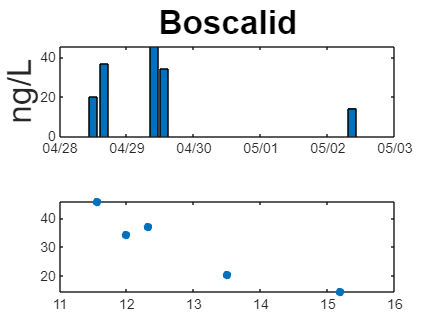

pestitle = 'Caffeine'

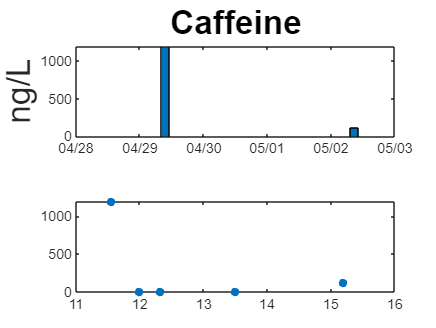

pestitle = 'Carbamazepine'

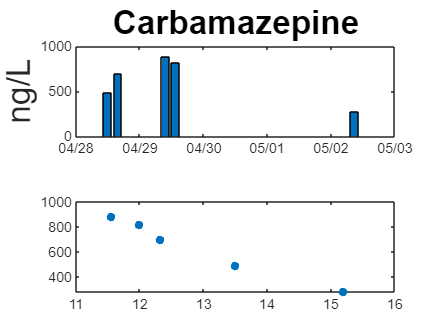

pestitle = 'Carbamazepine-10'

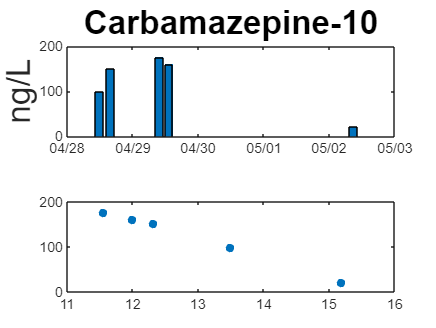

pestitle = '"Carbamazepine-trans-10, 11-dihydroxy"'

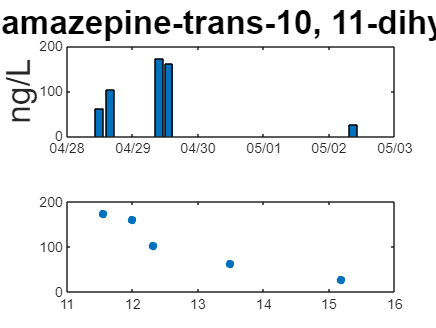

pestitle = 'Carbendazim'

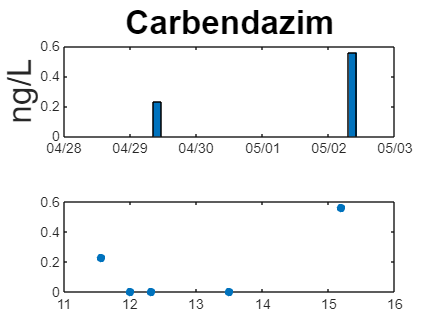

pestitle = 'Chlorantraniliprole'

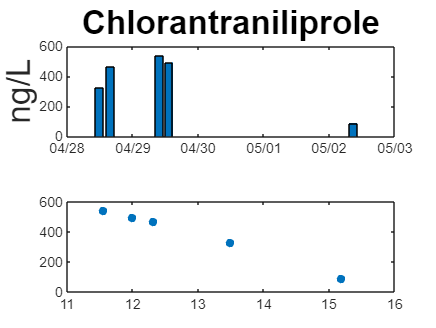

pestitle = 'Diuron'

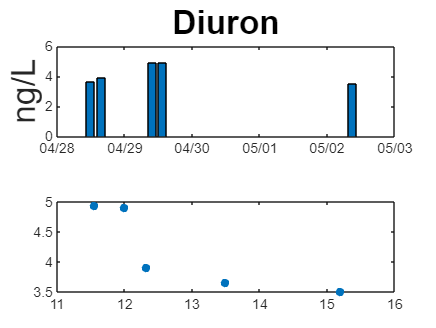

pestitle = 'Fenaminphos sulfoxide'

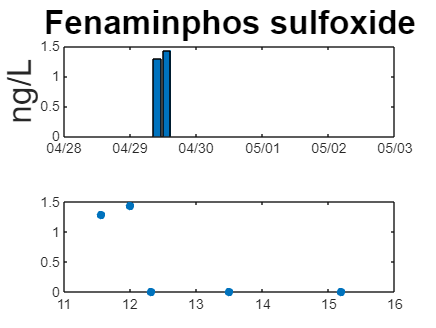

pestitle = 'Fluometuron'

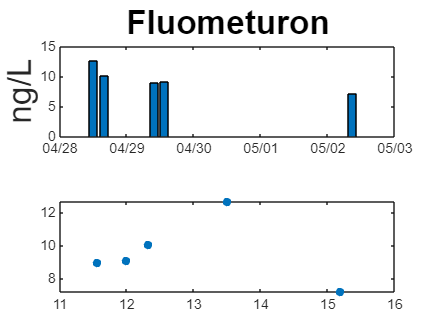

pestitle = 'Hexazinone'

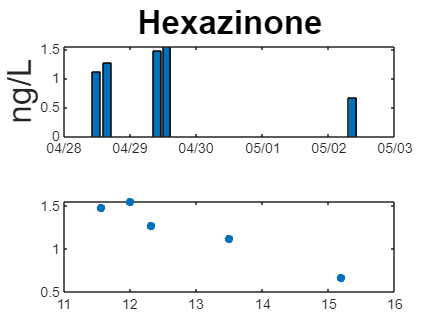

pestitle = 'Imidacloprid'

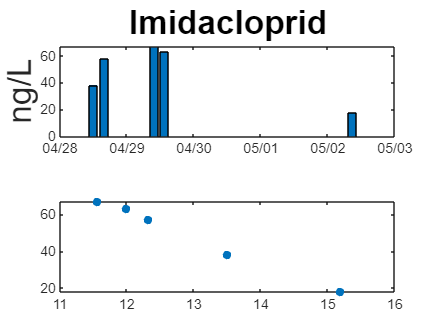

pestitle = 'Lamotrigine'

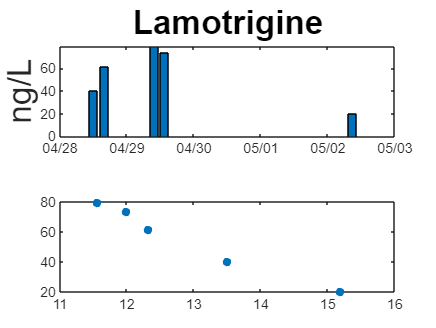

pestitle = 'Metalaxyl'

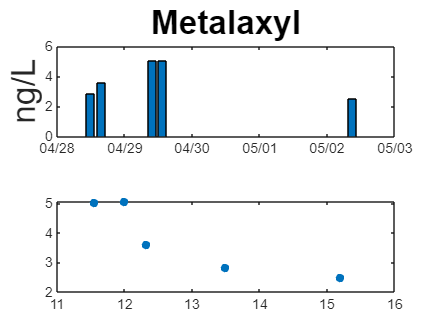

pestitle = 'Methoxyfenozide'

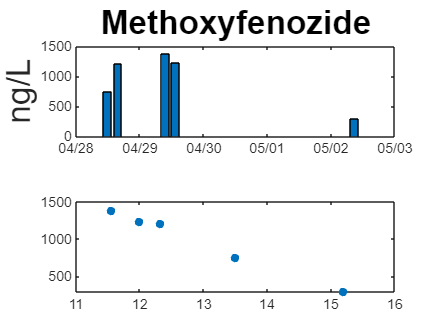

pestitle = 'Metolachlor'

pestitle = 'Penconazole'

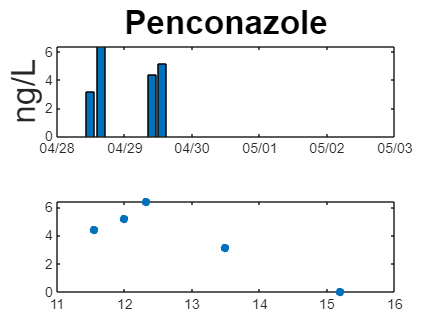

pestitle = 'Pirimicarb'

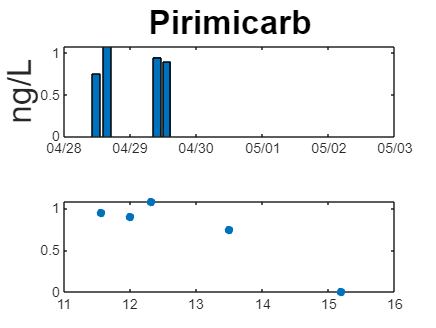

pestitle = 'Prometon'

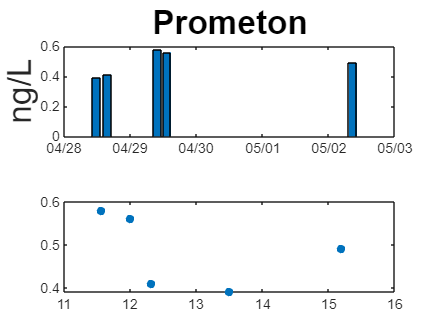

pestitle = 'Propamocarb'

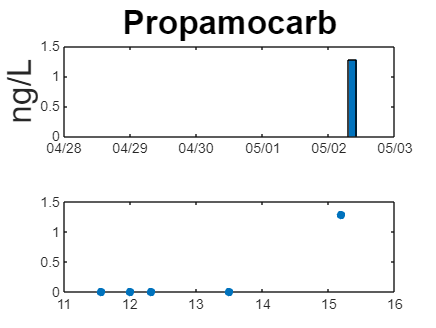

pestitle = 'Propazine'

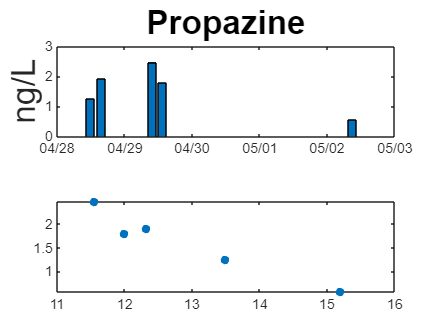

pestitle = 'propaxur'

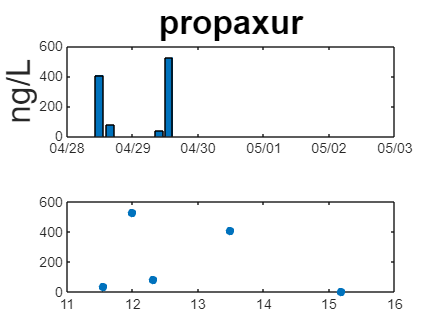

pestitle = 'Sulfamethoxazole'

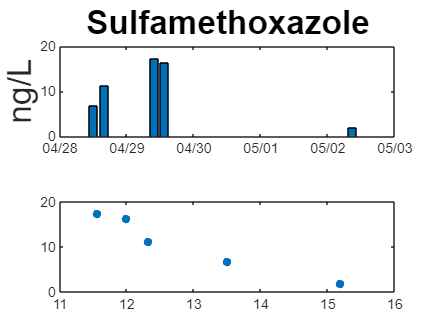

pestitle = 'Sulfapyridine'

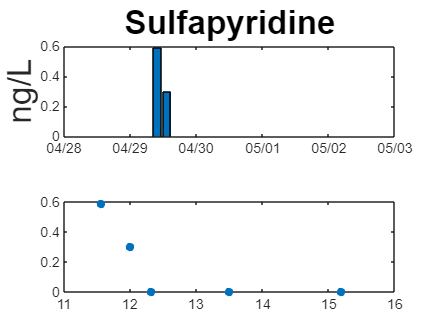

pestitle = 'Tebuconazole'

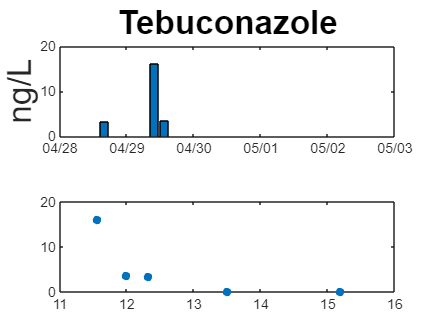

pestitle = 'Tebuthiuron'

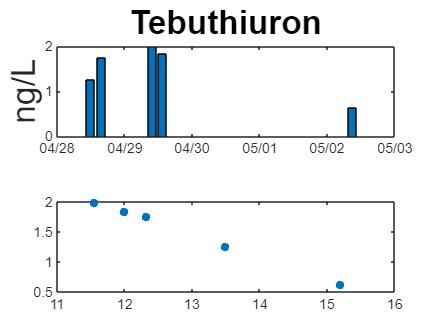

pestitle = 'Terbutryn'

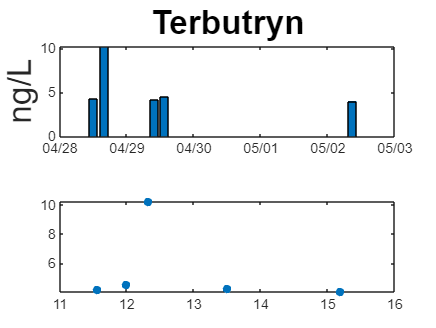

for i=1:x:length(pest_irr)
    figure(j)
subplot(2,1,1)
bar(date1,pest_irr(i:i+4));%The sample P23 was taken at 2.5.2021 8:40 =7.382783611111111e+05 was analyzed before the samples taken earlier (28-29 Apr)
%bar(date1,pestdata(i:i+4))
ylabel('ng/L','FontSize',20)
pestitle=lines{j}
title(pestitle,'Fontsize',20)
MAX(j)=max(pest_irr(i:i+4));
datetick
%datetick('x','dd-mmm HH:MM')
subplot(2,1,2)
plot(EC([1:3 5:6]),pest_irr(i:i+4),'.','MarkerSize',15);%EC has one more data (EC(4))than pesticides. it keeps the same trend consistently (decreasing)
%title(pestitle,'Fontsize',20)
[~,gof] = fit(EC([1:3 5:6]),pest_irr(i:i+4),ft);
R_2(j)=gof.rsquare;
j=j+1;
end

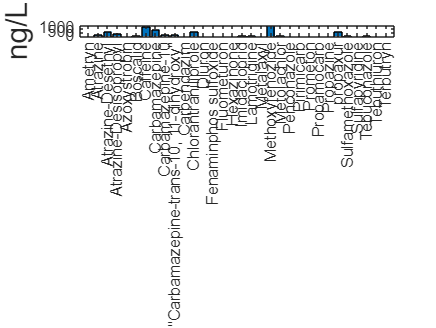

figure(222)
bar(lines(1:length(MAX)),MAX)
ylabel('ng/L','FontSize', 18)

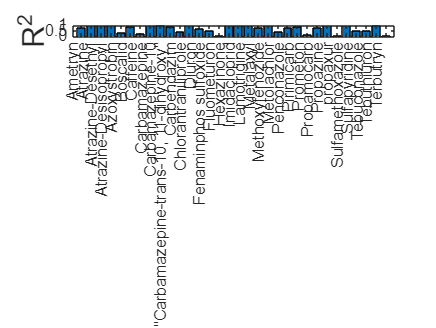

figure(333)
bar(lines(1:length(MAX)),R_2)
ylabel('R^2','FontSize', 18)